clear
clc

# Wing Design Calculator V1

#### By James Orendi

## Wing Sizing & Design

#### Input Data

wing_area = 132.7 ; % m^2
AR = 9.42 ; % Wing Aspect Ratio

sweep_type = 1 ;
wing_sweep = 48 ; % deg, Horizontal Tail Sweepback

wing_dihedral = 0; % deg

taper_ratio_t2r =0.35 ; % N/A, taper ratio between wingtip (numerator) and wing root (denominator)

#### Function Call

addpath([cd,'/Functions'])
[x_wing_data,y_wing_data,wing_span,c_r,c_t,wing_opp,wing_sweep,wing_dihedral_opp,wing_opp_2,wing_adj_2,wing_xlim,wing_ylim] = Planform_Calc_1taper(wing_area,AR,taper_ratio_t2r,wing_dihedral,wing_sweep,sweep_type) ;

#### Wing Planform Plot

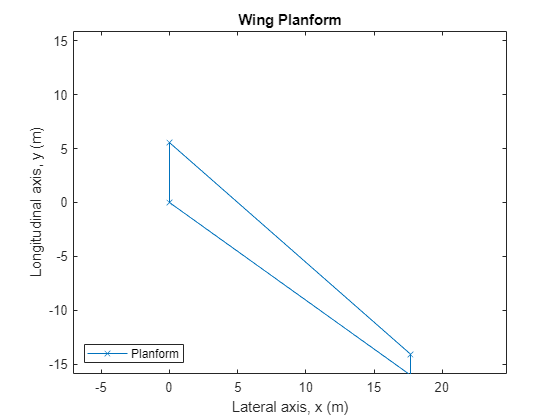

figure
plot(x_wing_data,y_wing_data,'x-')
xlim([wing_xlim(1),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_ylim,wing_ylim]) % Graphical Display View limits, y axis
legend("Planform","Location","Southwest")
title("Wing Planform")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")

#### MAC Graphical Calculation Function Call

[y_mac_Htail_data_1,y_mac_Htail_data_2,y_mac_Htail_data_3,y_mac_Htail_data_4,x_mac_Htail_data_1,x_mac_Htail_data_2,Htail_mac_graph_line_x_points,Htail_mac_graph_line_1_data,Htail_mac_graph_line_2_data,Htail_mac_graph_data_y,Htail_mac_graph_data_x,Htail_graph_AC,Htail_quarter_chord_x,Htail_quarter_chord_y] = Planform_MAC_1taper(wing_span,c_t,c_r,wing_opp);

### Wing MAC Graphical Plot

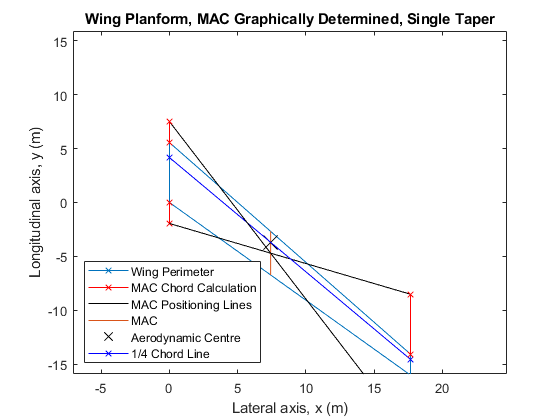

figure
plot(x_wing_data,y_wing_data,'x-')
hold on
plot(x_mac_Htail_data_1,y_mac_Htail_data_1,'x-','Color','r')
plot(Htail_mac_graph_line_x_points,Htail_mac_graph_line_1_data,'-','Color','k')
plot(Htail_mac_graph_data_x,Htail_mac_graph_data_y,'-','Color',[0.8500 0.3250 0.0980])
plot(Htail_graph_AC(1),Htail_graph_AC(2),'x', 'Color','k','MarkerSize',15)
plot(Htail_quarter_chord_x,Htail_quarter_chord_y,'x-', 'Color','b')
plot(Htail_mac_graph_line_x_points,Htail_mac_graph_line_2_data,'-','Color','k')
plot(x_mac_Htail_data_1,y_mac_Htail_data_2,'x-','Color','r')
plot(x_mac_Htail_data_2,y_mac_Htail_data_3,'x-','Color','r')
plot(x_mac_Htail_data_2,y_mac_Htail_data_4,'x-','Color','r')
xlim([wing_xlim(1),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_ylim,wing_ylim]) % Graphical Display View limits, y axis
legend("Wing Perimeter","MAC Chord Calculation","MAC Positioning Lines","MAC","Aerodynamic Centre","1/4 Chord Line","Location","Southwest")
title("Wing Planform, MAC Graphically Determined, Single Taper")
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off

### Full Wing Planform Plot

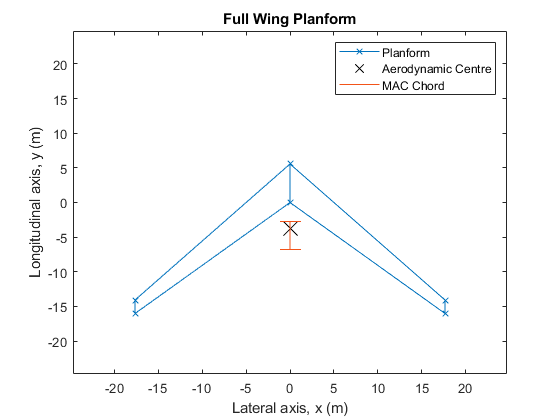

figure
plot(x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(0,Htail_graph_AC(2),'x', 'color','k','MarkerSize',15)
plot(-x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
plot([0 0],Htail_mac_graph_data_y,'_-','Color',[0.9500 0.3250 0.0980],'MarkerSize',15)
title("Full Wing Planform")
legend("Planform","Aerodynamic Centre","","MAC Chord")
xlim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off

## Wing Control Surface Sizing

### Input Data

wing_area_ratio_desired = 12/100 ; % N/A, Ratio of control surface area to wing area

CS_type = 2 ;

% SPANWISE PIVOT
aileron_span_ratio = 1 ; % N/A, the ratio of control surface span to Htail span, for spanwise pivot ONLY

% CONSTANT CHORD
aileron_chord_ratio = 0.5 ; % N/A, the ratio of control surface chord to Htail chord, for constant chord calculation ONLY

#### Function Call

if CS_type == 1
[Htail_x_control_surface_data,Htail_y_control_surface_data] = CS_Spanwise_Pivot(wing_area_ratio_desired,aileron_span_ratio,wing_opp_2,wing_adj_2,wing_span,c_r,c_t,wing_opp,wing_sweep) ;
elseif CS_type == 2
[Htail_x_control_surface_data,Htail_y_control_surface_data,Htail_S_control_ratio] = CS_Constant_Chord(wing_area_ratio_desired,wing_opp_2,wing_adj_2,wing_span,wing_sweep,aileron_chord_ratio,c_r,c_t,wing_opp) ;
end

### Full Horizontal Tail Control Surface Planform Plot

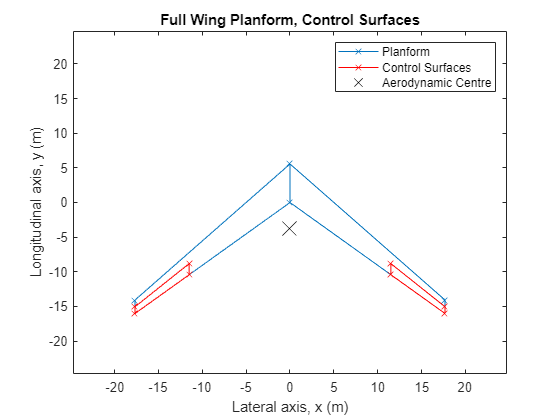

figure
plot(x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
hold on
plot(Htail_x_control_surface_data,Htail_y_control_surface_data,'x-',"Color",'r')
plot(0,Htail_graph_AC(2),'x', 'color','k','MarkerSize',15)
plot(-x_wing_data,y_wing_data,'x-',"Color",[0 0.4470 0.7410])
plot(-Htail_x_control_surface_data,Htail_y_control_surface_data,'x-',"Color",'r')

title("Full Wing Planform, Control Surfaces")
legend("Planform","Control Surfaces","Aerodynamic Centre")
xlim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, x axis
ylim([-wing_xlim(2),wing_xlim(2)]) % Graphical Display View limits, y axis
xlabel("Lateral axis, x (m)")
ylabel("Longitudinal axis, y (m)")
hold off